# Plotting in MATLAB

If $\mathbf{x}$ and $\mathbf{y}$ are vectors of the same size, the command `plot(x,y)` will plot all of the $\left(x_i ,y_i \right)$ pairs and each point will be connected to the next by a line segment. If the $x$-coordinates are taken close enough together, the graph should resemble a smooth curve. The command `plot(x,y,'o')` will mark the orderd pairs with `o`'s, but will not connect the points.

For example, to plot the function $f(x)= \frac{e^{x/10} \sin x}{x+1}$ on the interval $\left\lbrack 0,10\right\rbrack$, set

x=0:0.2:10;  % create a vector of values in the interval [0,10]
y=exp(x/10).*sin(x)./(x+1); %compute y as a function of x

(note the `.` before the `*` and `/`, as these operations must be done component-wise).

The command

plot(x,y)   % plot y vs x

will generate the graph  of the function. We can use the command `hold on` to plot more than one graph in the same figure. For example, the following commands will plot $\mathrm{sin}\;x$ in the same figure and add a legend:

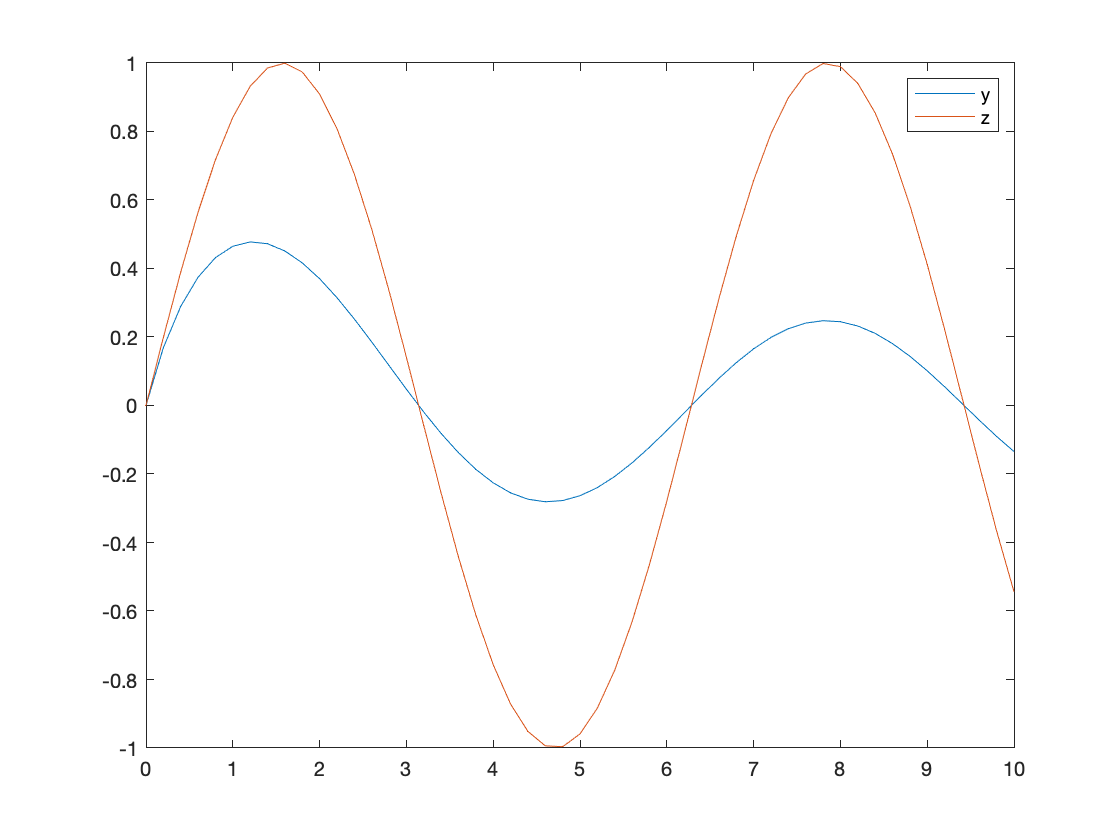

hold on    % hold the current figure
z = sin(x);   % Evaluate sin x and store it in the vector z
plot(x,z)  % plot z vs x
legend('y','z')
hold off   % release the figure

Given the points $\left(x_i ,y_i \right)$, rather than creating the vectors $\mathbf{x}$ and $\mathbf{y}$, an equivalent approach, which often is more convenient, is to create a $2\times 2$ matrix of data:


$$A=\left\lbrack \begin{array}{cccc}
x_1  & x_2  & \cdots  & x_n \\
y_1  & y_2  & \cdots  & y_n 
\end{array}\right\rbrack$$


then typing

In other words, the first row of A gives the $x$'s and the second row the $y$'s.

# Example 1

Consider the squrae whose vertices are $\left(0,0\right),\;\left(1,0\right),\;\left(1,1\right),\;\left(0,1\right)$ 

**(a)** Enter the $\mathbf{x}$ and $\mathbf{y}$ coordinatew of these points as MATLAB vectors by setting

x=[0,1,1,0,0]

x =      0     1     1     0     0


y=[0,0,1,1,0]

y =      0     0     1     1     0


The coordinates of the first point are repeated in the fourth column of $\mathbf{x}$ and $\mathbf{y}$ because we want to connect the fourth point back to the first. Plot $\mathbf{y}$ versus $\mathbf{x}$ and rescale the axis to $\left\lbrack -1,2\right\rbrack \times \left\lbrack -1,2\right\rbrack$ so that  the square does not take up the entire figure:

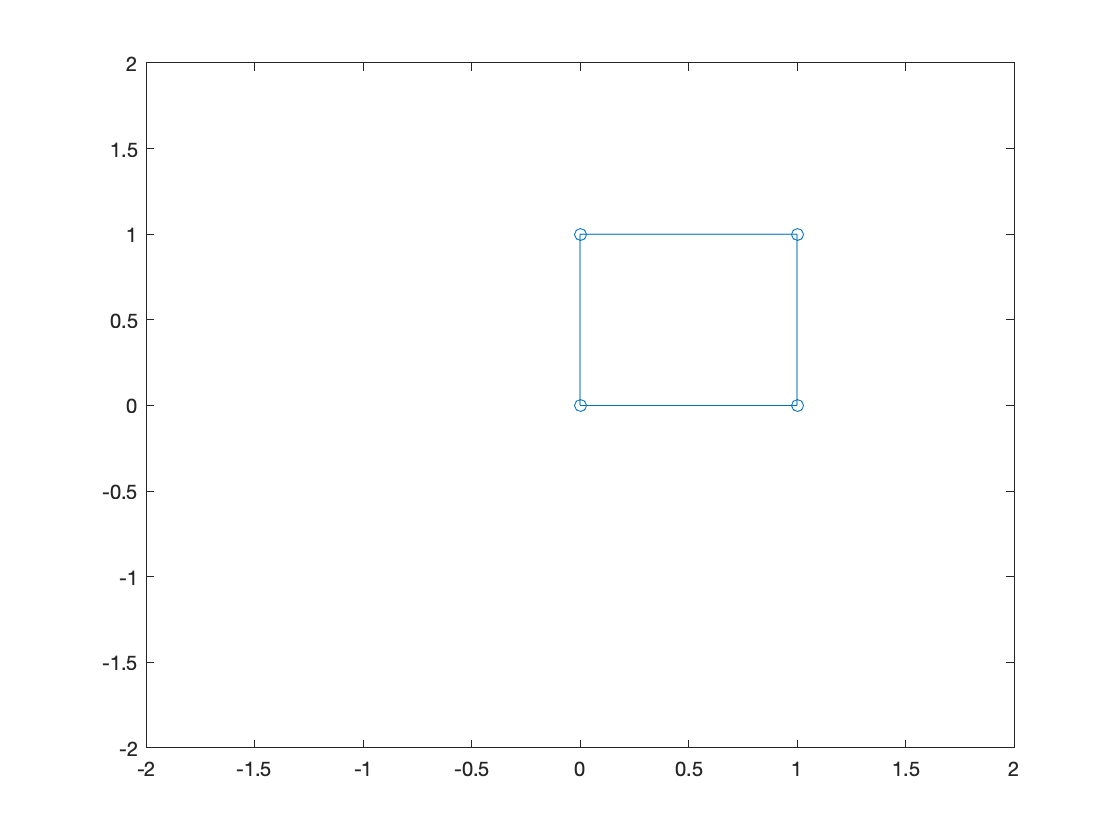

plot(x,y,'o-')  % plot y vs x using the option 'o-'
axis([-2,2,-2,2])

*Note:* The option 'o-' shows the plotted points and connects them.

**(b) **Now let's store the entire figure in a matrix `S` by storing the $x$-coordinate in the first row and the $y$-coordinates in the second row:

S=[0,1,1,0,0;0,0,1,1,0]

S =      0     1     1     0     0
     0     0     1     1     0


The square can then be plotted using the following command:

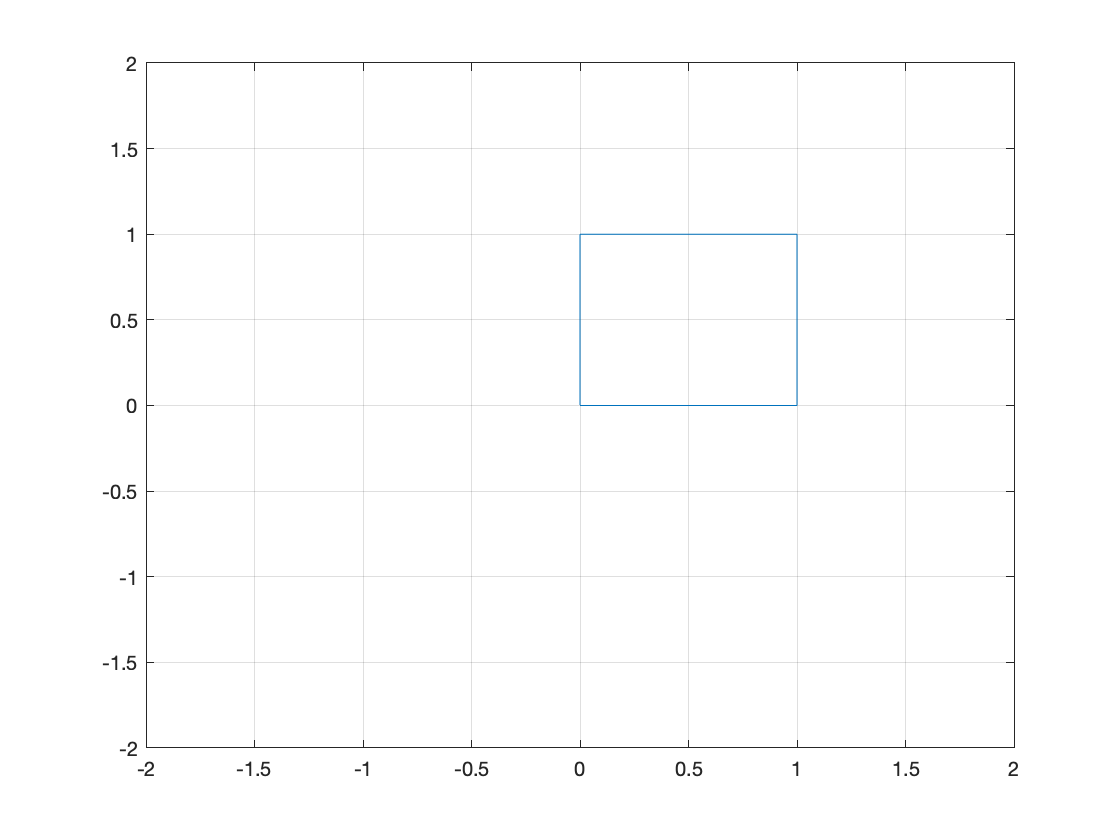

plot(S(1,:),S(2,:))
axis([-2,2,-2,2])
grid on

We set the axis again to $\left\lbrack -2,2\right\rbrack \times \left\lbrack -2,2\right\rbrack$ and we also added a grid using the command `grid on`.

# Rotation matrices in $\mathbb{R}^2$

Any 2-dimensional matrix of the form


$$Q=\left\lbrack \begin{array}{cc}
\mathrm{cos}\;\theta  & -\mathrm{sin}\;\theta \\
\mathrm{sin}\;\theta  & \mathrm{cos}\;\theta 
\end{array}\right\rbrack$$


is a rotation matrix. If $\mathbf{v}$ is a vector in $\mathbb{R}^2$, the product $Q\mathbf{v}$ is the vector $\mathbf{v}$ rotated $\theta$ radians around the origin $\left(0,0\right)$ in the counterclockwise direction.

To rotate the vector in the clockwise direction we simply replace $\theta$ with $-\theta$, thus


$$Q^{-1} =\left\lbrack \begin{array}{cc}
\mathrm{cos}\left(-\theta \right)\; & -\mathrm{sin}\left(-\theta \right)\;\\
\mathrm{sin}\left(-\theta \right)\; & \mathrm{cos}\left(-\theta \right)\;
\end{array}\right\rbrack$$


Since $\mathrm{cos}\left(-\theta \right)=\mathrm{cos}\theta$ and $\mathrm{sin}\left(-\theta \right)=-\mathrm{sin}\theta$, we have

                   
$$\;Q^{-1} =\left\lbrack \begin{array}{cc}
\mathrm{cos}\;\theta  & \mathrm{sin}\;\theta \\
-\mathrm{sin}\;\theta  & \mathrm{cos}\;\theta 
\end{array}\right\rbrack =Q^T$$


# Example 2

We can rotate the square S from Example 1 by an angle of $\frac{\pi }{6}$ in the counterclockwise direction by multiplying the matrix S by 


$$Q=\left\lbrack \begin{array}{cc}
\mathrm{cos}\left(\frac{\pi }{6}\right)\; & -\mathrm{sin}\left(\frac{\pi }{6}\right)\;\\
\mathrm{sin}\left(\frac{\pi }{6}\right)\; & \mathrm{cos}\left(\frac{\pi }{6}\right)\;
\end{array}\right\rbrack$$


The following code implements the rotation and plots the original picture together with the rotated one.

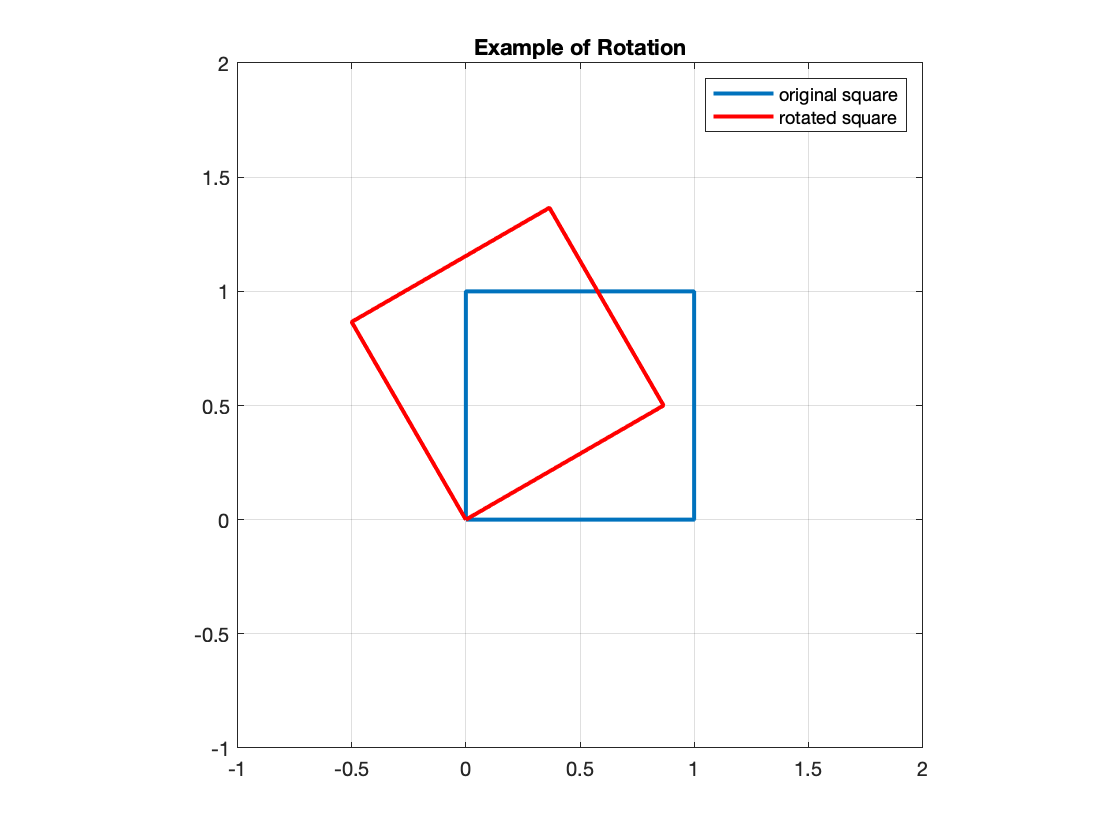

clear all; % clear all variables
clf; % clear all settings for the plot
S=[0 ,1 ,1 ,0 ,0;0 ,0 ,1 ,1 ,0];
plot(S(1 ,:),S(2 ,:),'linewidth' ,2); % plot the square
hold on;
theta =pi/6; % define the angle theta
Q=[cos(theta),-sin(theta); sin(theta),cos(theta)]; % rotation matrix
QS=Q*S; % rotate the square
plot(QS(1,:),QS(2,:),'-r','linewidth',2); % plot the rotated square
title('Example of Rotation'); % add a title
legend('original square ','rotated square ') % add a legend
axis equal ; axis ([ -1 ,2 , -1 ,2]); % set the window
grid on; % add a grid
hold off

**Remarks:**

- The` hold on` command concates all consequent plot commands on the same figure. Type `hold` `off` to start a new plot

- The` '-r'` plots the figure in red

- `grid on` adds a grid to the axis

- `axis equal` sets the same scale on the $x$ and $y$ axes

- `'linedwith',2 `sets the width of the line to 2 points =2/72 inches (the default is 0.5 points).

# Dilation and Contraction

Consider the matrix $D=\left\lbrack \begin{array}{cc}
\alpha_x  & 0\\
0 & \alpha_y 
\end{array}\right\rbrack$.

If we multiply this matrix by any vector $v={\left\lbrack \begin{array}{cc}
x & y
\end{array}\right\rbrack }^T$, we obtain the vector $\mathrm{Dv}={\left\lbrack \begin{array}{cc}
\alpha_{x\;} x & \alpha_y y
\end{array}\right\rbrack }^T$, which scales the vector by a factor $\alpha_x$ in the $x$-direction and by a factor $\alpha_y$ in the $y$-direction. The scalings are a dilation or contraction, depending on whether $\alpha_x$ and $\alpha_y$ are greater or smaller than one.

# Example 3

Consider the case where the dilation factors are $\alpha_x =2$ and $\alpha_y =3$. We can plot the original square S together with the dilated version by executing the following commands. 

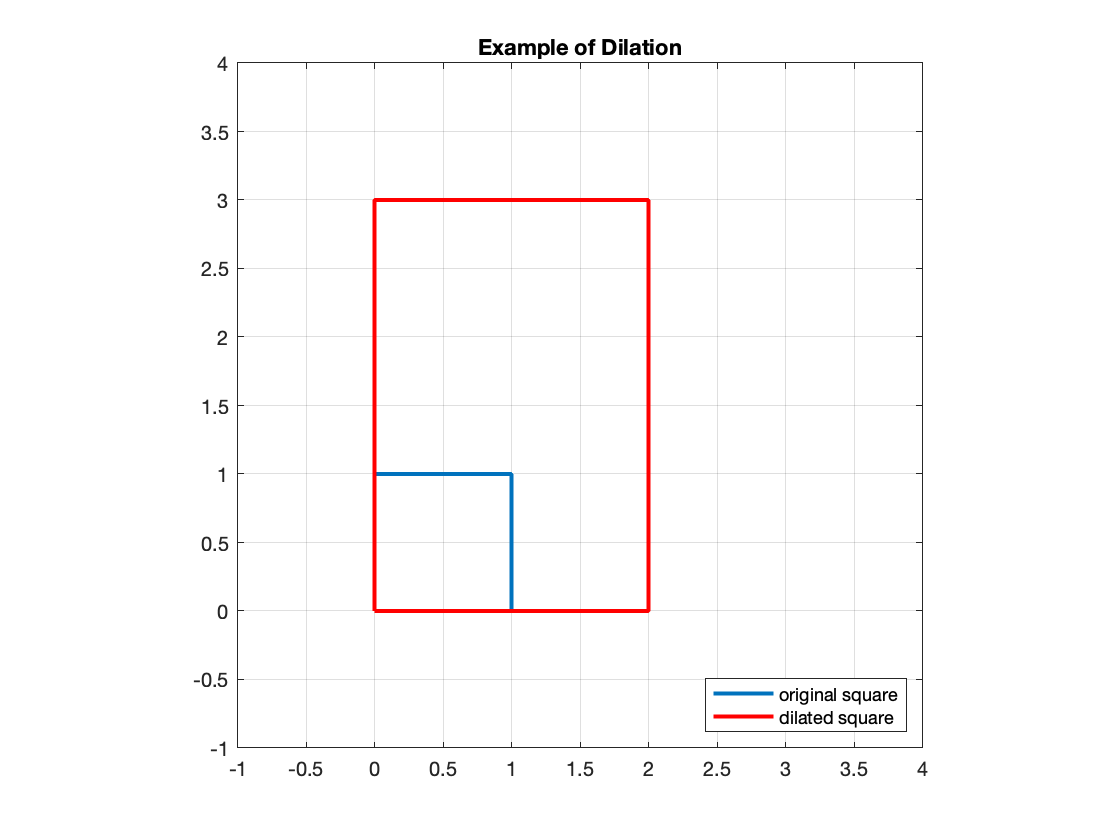

clf     % clear the figure
S=[0,1,1,0,0;0,0,1,1,0];  % enter the matrix S
plot(S(1,:),S(2,:),'linewidth',2)  % plot the original square
hold on    % concatenate the next plots
D = [2,0;0,3]; % dilation matrix
DS = D*S;   % dilate the matrix S
plot(DS(1,:),DS(2,:),'-r','linewidth',2) % plot the dilated square
title ('Example of Dilation')
legend('original square','dilated square','location','southeast')
grid on
axis equal, axis([-1,4,-1,4]) % adjust the axis and the window
hold off   % release the figure

**NOTE:**  By default the legend is position in the upper right corner. Here we changed the position to the lower right corner using the options `'location', southeast'`.

# Shear Matrices

A matrix of the form $T=\left\lbrack \begin{array}{cc}
1 & t_x \\
0 & 1
\end{array}\right\rbrack$ is a horizontal shear transformation. When we apply thius transformation, the y coordinates are unaffacted, but the $x$-coordinates are translated linearly with $y$.

Similarly, a matrix of the form $T=\left\lbrack \begin{array}{cc}
1 & 0\\
t_y  & 1
\end{array}\right\rbrack$ is a vertical shear transformation: the $x$-coordinatesare unaffacted, but the $y$ coordinates are translated linearly with $x$.

# Example 4

We will apply a horizontal shear transforamtion of 1 units. The matrix that accomplishes that is $T=\left\lbrack \begin{array}{cc}
1 & 1\\
0 & 1
\end{array}\right\rbrack \ldotp$ We can plot the original square together with the sheared version by executing the following commands. 

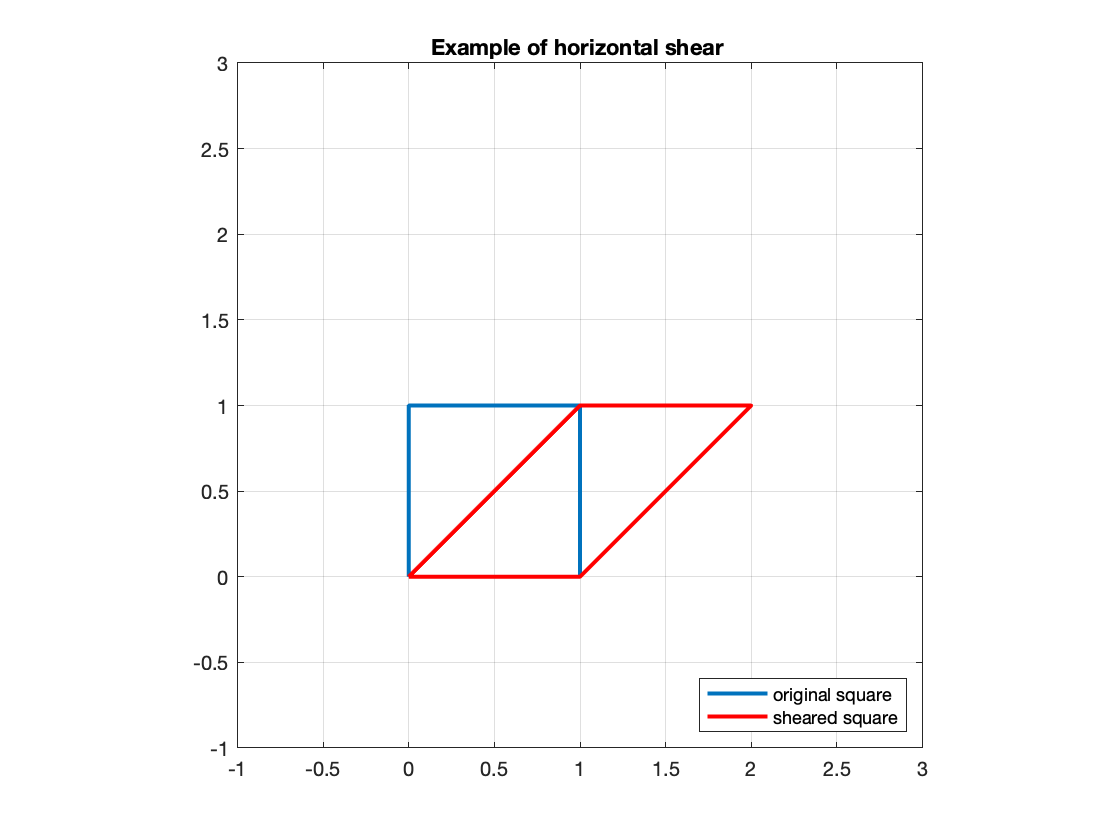

clf
S=[0 ,1 ,1 ,0 ,0;0 ,0 ,1 ,1 ,0];
plot(S(1,:),S(2,:),'linewidth',2) %plot the original square
hold on
T=[1,1; 0,1]; % shear transformation matrix
TS=T*S;  %apply the shear to the matrix S
plot(TS(1,:),TS(2,:),'-r','linewidth',2); % plot the sheared square
title('Example of horizontal shear')
legend('original square','sheared square','location',' southeast ')
axis equal, axis([-1,3,-1,3]); grid on % adjust the axis and the window
hold off